# 贝叶斯优化核自旋 vs 直接fit

### 给出数据

  在工具栏给出 Cv T

Cv = evalin('base','Cv');
T  = evalin('base','T');
% Cv_mJ = Cv*10^3;

### 拟合参数


$$C_v =\frac{a}{T^2 }+{\mathrm{bT}}^n +{\mathrm{CT}}^3$$


## 通过fit工具箱直接拟合

p=fittype('a*(x^-2) + b*x^n+c *x^3 ');
disp(coeffnames(p));

    {'a'}
    {'b'}
    {'c'}
    {'n'}



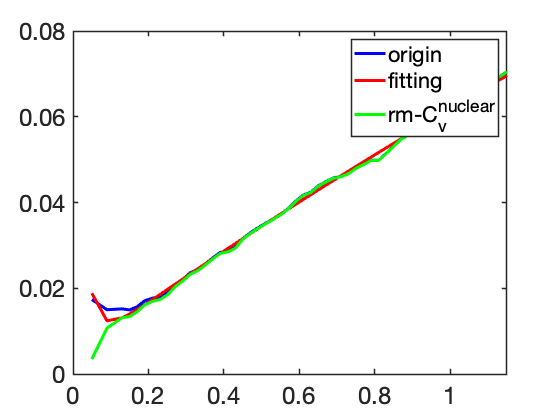

f=fit(T,Cv,p,'Lower',[0.0000,0.01,0.0003675,0.67],'Upper',[inf,inf,0.0003676,0.9]);

Nulear_coe = f.a;
powerlaw_coe = f.b;
powerlaw_index = f.n;
Debye_coe = f.c;
Cv_prime = Nulear_coe./(T.^2)+powerlaw_coe*T.^(powerlaw_index)+Debyecoe_bk *T.^3;
plotCvT;

disp(f)

     General model:
     f(x) = a*(x^-2) + b*x^n+c *x^3
     Coefficients (with 95% confidence bounds):
       a =   3.473e-05  (3.085e-05, 3.862e-05)
       b =     0.06138  (0.06101, 0.06175)
       c =   0.0003676  (fixed at bound)
       n =      0.8402  (0.8258, 0.8547)


## 贝叶斯优化

### 定义lossfunction

Debyecoe_bk = 0.00036765;
Debye_coe = Debyecoe_bk ;
% Debye_coe = HT_Debye_init;
% if you fix a Debye_coe by HT fit please uncomment the above line , give a fixed value 
loss_func = @(para) CvT_fit(para,Debyecoe);

Nulear_coe = optimizableVariable('Nulear_coe',[0,1]);
powerlaw_coe = optimizableVariable('powerlaw_coe',[0,20]);
powerlaw_index = optimizableVariable('powerlaw_index',[0.67,0.84]);
Debye_coe = optimizableVariable('Debye_coe',[0.00036765,0.00036766],'Optimize',false);
Max_Bayes = round(str2double("30"));
optimizablevector = [Debye_coe,Nulear_coe,powerlaw_coe,powerlaw_index];


results = bayesopt(loss_func,optimizablevector ,'Verbose',1,...
    'AcquisitionFunctionName','expected-improvement-plus',...
    'ExplorationRatio',0.5,...
    'MaxObjectiveEvaluations',Max_Bayes  ...
    )

拟合数据

powerlaw_coe = results.XAtMinObjective.powerlaw_coe ;
powerlaw_index = results.XAtMinObjective.powerlaw_index;
%Debye_coe  = results.XAtMinObjective.Debye_coe ;
% Debyecoe = Debyecoe_bk ;
Nulear_coe = results.XAtMinObjective.Nulear_coe ;
Cv_prime = Nulear_coe./(T.^2)+powerlaw_coe*T.^(powerlaw_index)+Debyecoe_bk *T.^3;
plotCvT;